Consider the example of an attractor with tetrahedral symmetry $T$ (here I will use $T$ to denote the representation). We define a polynomial map $f:\mathbb{R}^3 \rightarrow \mathbb{R}^3$ that spans the space that the $T$ acts on. It is our dynamical system that is equivariant with respect to $T$. We want to find the symmetry group of the attractor, which is a subset of $T$.

%clear variables
clear

%set seed for repeatability of results
rng('default')

ALPHA = 1;

ALPHA = 1

BETA = 1;

BETA = 1

GAMMA = 1;

GAMMA = 1

DELTA = -1;

DELTA = -1

LAMBDA = -2;

LAMBDA = -2



f = @(x,y,z, GAMMA, LAMBDA) LAMBDA*[x;y;z] + ALPHA*(x^2 + y^2 + z^2)*[x;y;z] + BETA*[y*z;x*z;x*y] + GAMMA*[x^3;y^3;z^3] + DELTA*[x*y^2;y*z^2;z*x^2];


Now, I'm going to create a dictionary of a representation of the tetrahedral group with the standard basis in $\mathbb{R}^3$. We will have the following keys as strings (see Xu, Chen for picture):

- E - identity

- Tx,Ty,Tz - Rotations of 180 degrees around the $ox,oy,oz$ axes

- R1,R2,R3,R4 - The 120 degree rotation with left thumb pointing towards $OA_1,OB_2, OA_3, OB_4$

- Q1,Q2,Q3,Q4 - The 240 degree rotations of (3)

- a - exchanges $A_1$ and $B_2$

- b - exchanges $A_1$ and $A_3$

- c - exchanges $A_1$ and $B_4$

- d - exchanges $B_2$ and $A_3$

- e - exchanges $B_2$ and $B_4$

- f - exchanges $A_3$ and $B_4$

- r - (a)(Tz)

- s - (a)(Ty)

- t - (a)(Q2)

- u - (a)(Q1)

- v - (a)(R1)

- w - (a)(R1)

% %Initialize empty dictionary
% T.GroupRep = dictionary();
% 
% T.GroupRep("E") = {eye(3)};
% 
% T.GroupRep("Tx") = {[1 0 0; 0 -1 0; 0 0 -1]};
% T.GroupRep("Ty") = {[-1 0 0; 0 1 0; 0 0 -1]};
% T.GroupRep("Tz") = {[-1 0 0; 0 -1 0; 0 0 1]};
% 
% T.GroupRep("R1") = {[0 1 0; 0 0 1; 1 0 0]};
% T.GroupRep("R2") = {[0 -1 0; 0 0 1; -1 0 0]};
% T.GroupRep("R3") = {[0 1 0; 0 0 -1; -1 0 0]};
% T.GroupRep("R4") = {[0 -1 0; 0 0 -1; 1 0 0]};
% 
% T.GroupRep("Q1") = {[0 0 1; 1 0 0; 0 1 0]};
% T.GroupRep("Q2") = {[0 0 -1; -1 0 0; 0 1 0]};
% T.GroupRep("Q3") = {[0 0 -1; 1 0 0; 0 -1 0]};
% T.GroupRep("Q4") = {[0 0 1; -1 0 0; 0 -1 0]}
% 
% T.GroupRep("a") = {[1 0 0; 0 0 -1; 0 -1 0]};
% T.GroupRep("b") = {[0 -1 0; -1 0 0; 0 -1 0]};
% T.GroupRep("c") = {[0 0 -1; 0 1 0; -1 0 0]};
% T.GroupRep("d") = {[0 0 1; 0 1 0; 1 0 0]};
% T.GroupRep("e") = {[0 1 0; 1 0 0; 0 0 1]};
% T.GroupRep("f") = {[1 0 0; 0 0 1; 0 1 0]};
% 
% T.GroupRep("r") = {[-1 0 0; 0 0 -1; 0 1 0]};
% T.GroupRep("s") = {[-1 0 0; 0 0 1; 0 -1 0]};
% T.GroupRep("t") = {[0 0 -1; 0 -1 0; 1 0 0]};
% T.GroupRep("u") = {[0 0 1; 0 -1 0; -1 0 0]};
% T.GroupRep("v") = {[0 -1 0; 1 0 0; 0 0 -1]};
% T.GroupRep("w") = {[0 1 0; -1 0 0; 0 0 -1]};


Using this dictionary, I want to verify that $f$ is equivariant. That is, for all representations $\gamma$ in the tetrahedral group, we want $f(\gamma\cdot x) = \gamma \cdot f(x)$. When using brute force, Matlab fails, but I claim that we can verify via brute force that $f$ is equivariant (are there any clever tricks or theorems to verify this without using brute force?)

%Matlab couldn't prove the following

%elements = values(T.GroupRep);

% syms a b c
% 
% syms a b c;
% for i=1:length(elements)
%     element = elements{i};
%     inputs = element*[a;b;c];
%     isAlways(f(inputs(1),inputs(2),inputs(3)) == element*f(a,b,c))
% end

Now we have the observable $\phi: \mathbb{R}^3 \rightarrow \mathbb{R}^5$. Indeed, it is also equivariant with respect to $T$ (why?). For $T$ to act on $\mathbb{R}^5$, we can extend the tetrahedron, noticing that the appended dimensions are symmetric with respect to the dihedral group $D_2$. Accordingly, take the direct sum of the matrix representations of elements in $T$ and $D_2$ for our new group. 

phi = @(x,y,z) [y.*z;x.*z;x.*y;2*x.^2-y.^2-z.^2;2*y.^2-x.^2-z.^2];

Now, we can use *Proposition 5.8 *to show that $\phi$ is a detective. Here $W_\phi$ is the span of $\phi$. Since $span(\phi) = \mathbb{R}^5$ (why?), we have that $W_{\phi} = W$. Moreover, $W = \mathbb{R}^5$ *distinguishes* all subgroups. That is, for all $\Delta, \Sigma, Y \subset T$ $\text{dim}(Fix_{\mathbb{R}^5}(\Delta)) < \text{dim}(Fix_{\mathbb{R}^5}(\Sigma)) < \text{dim}(Fix_{\mathbb{R}^5}(Y))$ whenever $$\Delta \supset \Sigma \supset Y$ where each is a proper subset and $Fix_W(\Gamma) = \{x\in W \ : \ \gamma x = x  \ \forall\gamma\in\Gamma\}$. Indeed, by Theorem 4.5, since $\mathbb{R}^5 = \mathbb{R}^3 \oplus \mathbb{R}^2$ where $\mathbb{R}^3$ and $\mathbb{R}^2$ are irreducible subspaces (this is an abuse of notation), $\mathbb{R}^5$ distinguishes subgroups.

To find the isotropy group $\Sigma(A) = \{\gamma \in T \ : \ \gamma A = A\}$,  we can compute the distance from an observation 

$K_{\phi}(A) = \int_A\phi \ d \mu$ (where $\mu$ is the Lebesgue measure in $\mathbb{R}^3$)

 to the fixed-point subspace $\text{Fix}(\gamma)$ for some $\gamma \in T$. The group element $\gamma$ is in the isotropy group $\Sigma(A)$ if the distance is zero. For the tetrahedral group, we have seven distances to compute: the four axes of the tetrahdron and the extension of each axis in $\mathbb{R}^3$ into $\mathbb{R}^5$. We can write this precisely as follows. Let $\mathbb{R}\{\mathbf{v}\}$ denote the span of the vector $\mathbf{v} \in \mathbb{R}^5$. Then our fixed point subspaces are given by

- 
$$\mathbb{R}\{(1,1,1,0,0)\}$$


- 
$$\mathbb{R}\{(1,-1,1,0,0)\}$$


- 
$$\mathbb{R}\{(1,1,-1,0,0)\}$$


- 
$$\mathbb{R}\{(-1,1,1,0,0)\}$$


- 
$$\mathbb{R}\{(1,0,0,0,0)\} \oplus \mathbb{R}^2$$


- 
$$\mathbb{R}\{(0,1,0,0,0)\} \oplus \mathbb{R}^2$$


- 
$$\mathbb{R}\{(0,0,1,0,0)\} \oplus \mathbb{R}^2$$


.We first want to compute the distance $d(K_\phi(A), \mathbb{R}\{(1,1,1,0,0)\})$. Since $\phi$ is vector-valued, we can integrate term-by-term. Let  $(\phi_1,\phi_2,\phi_3,\phi_4,\phi_5):=K_{\phi}(A) = \int_A\phi \ d \mu$. The distance between $K_{\phi}(A)$ and any point $y\in \mathbb{R}\{(1,1,1,0,0)\}$is given by


$$d(K_\phi(A), \mathbb{R}\{(1,1,1,0,0)\})^2 = \sum_{i=1}^5(\phi_i - y_i)^2 = \sum_{i=1}^3(\phi_i-y_i)^2 + \phi_4^2 + \phi_5^2$$


where we have the second inequality because for any element in $\mathbb{R}\{(1,1,1,0,0)\}$, the fourth and fifth components are zero. To find the minimum distance, we need to find

$\min_{y\in \mathbb{R}\{(1,1,1,0,0)\}} \sum_{i=1}^3(\phi_i - y_i)^2 = \min_{t\in\mathbb{R}}\|t(1,1,1) - (\phi_1,\phi_2,\phi_3)\| = \min_{t\in\mathbb{R}}((\phi_1-t)^2 + (\phi_2 - t)^2 + (\phi_3-t)^2)$.

We are minimizing a function that is differentiable with respect to $t$, so the minima occur at critical points. To find the critical points, we need to find $t$ such that

$\frac{\partial}{\partial t}((\phi_1-t)^2 + (\phi_2 - t)^2 + (\phi_3-t)^2) = -2(\phi_1 + \phi_2 + \phi_3 - 3t) = 0$.

This implies that $t = \frac{\phi_1 + \phi_2 + \phi_3}{3}$. At such a $t$, the function value is given by


$$\left(\phi_1 -  \frac{\phi_1 + \phi_2 + \phi_3}{3}\right)^2 + \left(\phi_2 -  \frac{\phi_1 + \phi_2 + \phi_3}{3}\right)^2 + \left(\phi_3 -  \frac{\phi_1 + \phi_2 + \phi_3}{3}\right)^2$$



$$= \phi_1^2-\frac{2}{3}(\phi_1^2 + \phi_2\phi_1 + \phi_3\phi_1) + \left(\frac{\phi_1 + \phi_2 + \phi_3}{3}\right)^2$$



$$+\phi_2^2 -\frac{2}{3} (\phi_1\phi_2 + \phi_2^2 + \phi_3\phi_2) + \left( \frac{\phi_1 + \phi_2 + \phi_3}{3}\right)^2$$



$$+\phi_3^2 -\frac{2}{3}(\phi_1\phi_3 + \phi_2^2 + \phi_3^2) + \left(\frac{\phi_1 + \phi_2 + \phi_3}{3}\right)^2$$


plugging in $\left(\frac{\phi_1 + \phi_2 + \phi_3}{3}\right)^2 = \frac{1}{9}(\phi_1^2 + \phi_1\phi_2 + \phi_1\phi_3 + \phi_2\phi_1 + \phi_2^2 + \phi_2\phi_3 + \phi_1\phi_3 + \phi_2\phi_3 + \phi_3^2)$ and combining like terms, we have that

$d(K_\phi(A), \mathbb{R}\{(1,1,1,0,0)\})^2  = \frac{2}{3}(\phi_1^2 + \phi_2^2 + \phi_3^2 - \phi_1\phi_2 + \phi_1\phi_3 - \phi_2\phi_3) + \phi_4^2 + \phi_5^2$**.**

Similarly, we can compute that 

$d(K_\phi(A), \mathbb{R}\{(1,-1,1,0,0)\})^2  = \frac{2}{3}(\phi_1^2 + \phi_2^2 + \phi_3^2 - \phi_1\phi_2 + \phi_1\phi_3 + \phi_2\phi_3) + \phi_4^2 + \phi_5^2$**.**

$d(K_\phi(A), \mathbb{R}\{(1,1,-1,0,0)\})^2  = \frac{2}{3}(\phi_1^2 + \phi_2^2 + \phi_3^2 + \phi_1\phi_2 + \phi_1\phi_3 - \phi_2\phi_3) + \phi_4^2 + \phi_5^2$**.**

$d(K_\phi(A), \mathbb{R}\{(-1,1,1,0,0)\})^2  = \frac{2}{3}(\phi_1^2 + \phi_2^2 + \phi_3^2 + \phi_1\phi_2 - \phi_1\phi_3 + \phi_2\phi_3) + \phi_4^2 + \phi_5^2$**.**

Furthermore, we can see that

$d(K_\phi(A), \mathbb{R}\{(1,0,0,0,0)\}\oplus\mathbb{R}^2)^2 = \phi_2^2 + \phi_3^2$,

$d(K_\phi(A), \mathbb{R}\{(0,1,0,0,0)\}\oplus\mathbb{R}^2)^2 = \phi_1^2 + \phi_3^2$,

$d(K_\phi(A), \mathbb{R}\{(0,0,1,0,0)\}\oplus\mathbb{R}^2)^2 = \phi_1^2 + \phi_2^2$,

since each of the fixed point subspaces spans the last two components and one of the first three components, otherwise it is zero. Note that if all distances are zero, the attractor has full tetrahedral symmetry. If any of the first four distances are zero, then the attractor has symmetry in $\mathbb{R}^3$ (why?). Similarly, if any of the last three distances are zero, the attractor has full symmetry in the extended $\mathbb{R}^2$ dimensions (why?). If the last three distances are all zero but the first four are nonzero, then the attractor has $D_2$ symmetry. If all distances are nonzero, the attractor has trivial symmetry.

Now, we want to compute the distances above. As proved in the paper, we may assume that the ergodic theorem is valid and (approximately) compute


$$K_{\phi}^E(x_0)=\lim_{N\rightarrow\infty}\frac{1}{N}\sum_{j=0}^N\phi(f^j(x_0))$$


for a discrete dynamical system. Instead of waiting until $K_{\phi}^E(x_0)$ converges, we will compute $\frac{1}{N}\sum_{J=0}^N\phi(f^j(x_0))$ at an $N$ such that the dynamical system converges to an attractor. We will define numerical convergence as follows. We will choose a region containing the attractor (guesswork for the region) and divide the region into boxes. Starting at an an arbitrary point in $\mathbb{R}^3$ we iterate our dynamical system $f$ 1000 times for each *epoch. *After each epoch, we will say that the system has converged if the net  increase in the number of boxes occupied is 0.001 or less of the total number of boxes occupied in the previous epoch. Furthermore, we will vary the parameters $-2.1 < \lambda < -1.6$ and $0.4 < \gamma < 1.4$ and compute the symmetry of the attractor for the different parameters. Of course, since we are numerically determining the symmetries, we must discretize the ranges of $\gamma$ and $\lambda$. Indeed, we will *snake through* the grid as follows. First fix $\lambda$ and increase $\gamma$ by steps of $0.01$ until it reaches its maximum values $-1.6$. Then increase $\lambda$ by $0.005$ and decrease  $\gamma$ by steps of $0.01$ until it reaches its minimum values $0.4$. Repeat this process until $\lambda$ reaches its maximum values and $\gamma$ reaches its minimum value (i.e. the whole parameter space is covered).

GAMMA = 0.4000

distances =      0     0     0     0     0     0     0


GAMMA = 0.6500

distances =      0     0     0     0     0     0     0


GAMMA = 0.9000

distances =      0     0     0     0     0     0     0


GAMMA = 1.1500

distances =      0     0     0     0     0     0     0


GAMMA = 1.4000

distances =      0     0     0     0     0     0     0


GAMMA = 1.6500

LAMBDA = -1.9750

GAMMA = 1.4000

GAMMA = 0.4000

distances = 1.0e-05 *

    0.1117    0.2170    0.2170    0.2032    0.0945    0.0822    0.0499


GAMMA = 0.6500

distances = 1.0e-06 *

    0.4151    0.7160    0.7160    0.4438    0.1570    0.4565    0.3005


GAMMA = 0.9000

distances = 1.0e-05 *

    0.4047    0.2556    0.2556    0.2238    0.2528    0.1480    0.1071


GAMMA = 1.1500

distances =     0.1092    0.3167    0.3167    0.3039    0.1331    0.1822    0.1672


GAMMA = 1.4000

distances = 1.0e-04 *

    0.0897    0.0694    0.0694    0.0820    0.1222    0.0023    0.1211


GAMMA = 1.6500

LAMBDA = -1.8500

GAMMA = 1.4000

GAMMA = 0.4000

distances =     0.0289    0.0289    0.0289    0.0000    0.0216    0.0216    0.0217


GAMMA = 0.6500

distances =     0.0218    0.0218    0.0218    0.0000    0.0163    0.0163    0.0163


GAMMA = 0.9000

distances = 1.0e-04 *

    0.0814    0.1142    0.1142    0.0973    0.0219    0.0370    0.0189


GAMMA = 1.1500

distances =     0.3112    0.3111    0.3111    0.3111    0.0531    0.0531    0.0000


GAMMA = 1.4000

distances =     0.4157    0.4156    0.4156    0.4156    0.0000    0.0487    0.0487


GAMMA = 1.6500

LAMBDA = -1.7250

GAMMA = 1.4000

GAMMA = 0.4000

distances =     0.0000    0.0186    0.0186    0.0186    0.0140    0.0140    0.0140


GAMMA = 0.6500

distances =     0.0315    0.0315    0.0315    0.0315    0.0236    0.0236    0.0236


GAMMA = 0.9000

distances =     0.0430    0.0430    0.0430    0.0430    0.0322    0.0322    0.0322


GAMMA = 1.1500

distances =     0.0372    0.0372    0.0372    0.0372    0.0279    0.0279    0.0279


GAMMA = 1.4000

distances =     0.0312    0.0312    0.0312    0.0312    0.0234    0.0234    0.0234


GAMMA = 1.6500

LAMBDA = -1.6000

GAMMA = 1.4000

GAMMA = 0.4000

distances =     0.0000    0.0088    0.0088    0.0088    0.0066    0.0066    0.0066


GAMMA = 0.6500

distances =     0.0390    0.0000    0.0000    0.0390    0.0292    0.0292    0.0292


GAMMA = 0.9000

distances =     0.0371    0.0000    0.0000    0.0371    0.0278    0.0278    0.0278


GAMMA = 1.1500

distances =     0.0333    0.0000    0.0000    0.0334    0.0250    0.0250    0.0250


GAMMA = 1.4000

distances =     0.0301    0.0000    0.0000    0.0301    0.0225    0.0225    0.0225


GAMMA = 1.6500

LAMBDA = -1.4750

GAMMA = 1.4000

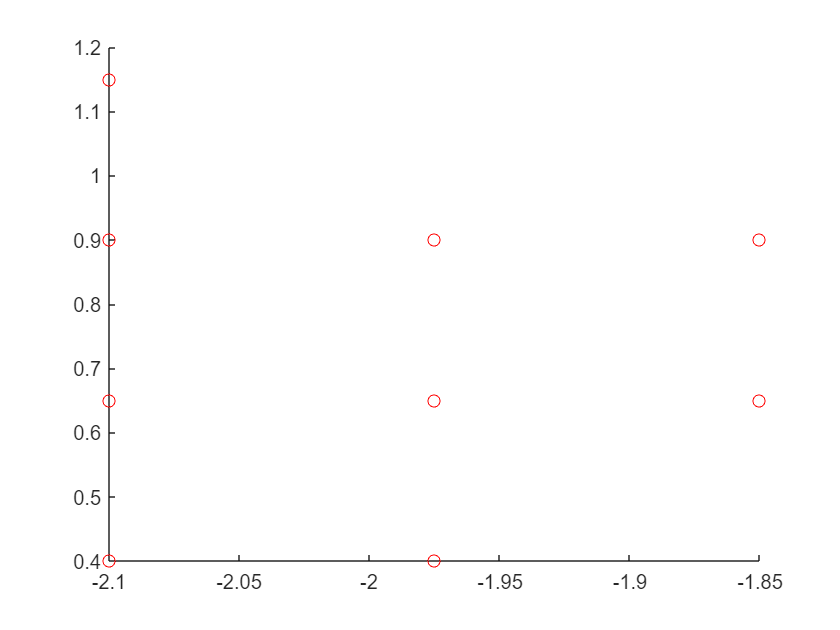


%initial data chosen to mimic paper (p.76)
x0 = 0.75;

y0 = 0.5;
z0 = 0.66;

%initialize
GAMMA = 0.4;
LAMBDA = -2.1;
g_step = 1/10;
l_step = 0.5/10;

%for recording which parameters had which type of symmetry
symmTx = [];
symmTy = [];

symmDx = [];
symmDy = [];

symmR3x = [];
symmR3y = [];

symmR2x = [];
symmR2y = [];

symmtrivx = [];
symmtrivy = [];

blowupx = [];
blowupy = [];


while LAMBDA < -1.6

    GAMMA = 0.4;
    while GAMMA <= 1.4
        average_sum = ergodic_avg(x0, y0, z0, f, phi, GAMMA, LAMBDA);
        distances = compute_dist(average_sum);
        
        
        %recording type of symmetry
        %in paper, if distance less than or equal to 0.005, essentially
        %zero
        if sum(isnan(distances)) ~= 0 
            blowupx(end+1) = LAMBDA;
            blowupy(end+1) = GAMMA;
        elseif max(abs(distances)) <= 0.005
            symmTx(end+1) = LAMBDA;
            symmTy(end+1) = GAMMA;
        elseif max(abs(distances(5:7))) <= 0.005 && min(abs(distances(1:4))) > 0.005
            symmDx(end+1) = LAMBDA;
            symmDy(end+1) = GAMMA;
        elseif min(abs(distances(1:4))) <= 0.005
            symmR3x(end+1) = LAMBDA;
            symmR3y(end+1) = GAMMA;
        elseif min(abs(distances(5:7))) <= 0.005
            symmR2x(end+1) = LAMBDA;
            symmR2y(end+1) = GAMMA;
        else
            symmtrivx(end+1) = LAMBDA;
            symmtrivy(end+1) = GAMMA;
        end


    GAMMA = GAMMA + g_step;
    end

    LAMBDA = LAMBDA + l_step;
    GAMMA = 1.4;
    while GAMMA >= 0.4
        average_sum = ergodic_avg(x0, y0, z0, f, phi, GAMMA, LAMBDA);
        distances = compute_dist(average_sum);


        %recording type of symmetry
        %in paper, if distance less than or equal to 0.005, essentially
        %zero
        if sum(isnan(distances)) ~= 0 
            blowupx(end+1) = LAMBDA;
            blowupy(end+1) = GAMMA;
        elseif max(abs(distances)) <= 0.005
            symmTx(end+1) = LAMBDA;
            symmTy(end+1) = GAMMA;
        elseif max(abs(distances(5:7))) <= 0.005 && min(abs(distances(1:4))) > 0.005
            symmDx(end+1) = LAMBDA;
            symmDy(end+1) = GAMMA;
        elseif min(abs(distances(1:4))) <= 0.005
            symmR3x(end+1) = LAMBDA;
            symmR3y(end+1) = GAMMA;
        elseif min(abs(distances(5:7))) <= 0.005
            symmR2x(end+1) = LAMBDA;
            symmR2y(end+1) = GAMMA;
        else
            symmtrivx(end+1) = LAMBDA;
            symmtrivy(end+1) = GAMMA;
        end

    GAMMA = GAMMA - g_step;
    end
end


%plotting symmetries in parameter space
scatter(symmTx, symmTy, 'r')
hold on
scatter(symmR3x, symmR3y, 'g')
hold on
scatter(symmR2x, symmR2y, 'b')
hold on
scatter(symmDx, symmDy, 'm')
hold on
scatter(blowupx, blowupy, 'y')
hold on
scatter(symmtrivx, symmtrivy, 'c')
hold off

function [xvec, yvec, zvec] = epoch(x0,y0,z0, f, GAMMA, LAMBDA)
%Given the initial values of the dynamical system and the dynamical 
%system f, this function will iterate the dynamical system 1000
%times (i.e. one epoch) and store the trajectory as three separate 
%vectors for the x,y, and z coordinates.


    %initializing data points
    x = x0;
    y = y0;
    z = z0;
    %initializing vectors to store data
    xvec = [x];
    yvec = [y];
    zvec = [z];
    
    %computing discrete dynamical system f
    %Up to 999 because we already have the initial condition in our data
    for i=1:999
        %evaluating function f
        vec = f(x,y,z, GAMMA, LAMBDA);
        
        x = vec(1);
        y = vec(2);
        z = vec(3);
    
        xvec(end+1) = x;
        yvec(end+1) = y;
        zvec(end+1) = z;
    end
end





function bins = occ_boxes(xvec, yvec, zvec)
%Given data points for the dynamical system (separately for x, y, and z), 
% this function will return a 3 x 1000 array where each column 
% represents a "bin" in the discretized system
    
    %splitting the range [-1,1] into boxes of width 0.00001
    edges = -1:0.00001:1;
    
    xdata = discretize(xvec, edges);
    ydata = discretize(yvec, edges);
    zdata = discretize(zvec, edges);

    bins = [xdata;ydata;zdata];
end





function total_sum = ergodic_sum(xvec, yvec, zvec, phi)
%Given the iterations of the dynamical system (separately for x,y,z),
% and the detective phi, this function computes the ergodic sum:
% sum phi(f^j(x_0)), a 5-vector
%
%NOTE THIS IS THE SUM NOT THE AVERAGE

    phi_iterates = phi(xvec, yvec, zvec);
    total_sum = sum(phi_iterates, 2);   %5-vector 
end



function average_sum = ergodic_avg(x0,y0,z0, f, phi, GAMMA, LAMBDA)
%this function will run epochs of the dynamical system until convergence
%(as defined by the paper). Then it will compute the ergodic average, which
%is our approximation of the observation K_phi(A)

    %initialization
    increase_bins = 1;
    prev_boxes = double.empty(3,0);
    filled_boxes = double.empty(3,0);
    N=0;
    total_sum = [0;0;0;0;0];
    
    
    while increase_bins > 0.001
        
        %store boxes filled at previous iterations
        prev_boxes = (union(prev_boxes',filled_boxes', 'rows'))';
    
        %iterate the dynamical system 1000 times
        [xvec,yvec,zvec] = epoch(x0,y0,z0, f, GAMMA, LAMBDA);
        N = N + 1000;
        
        %stop the loop if divergence
        if sum(isnan([xvec, yvec, zvec]),'all') ~= 0 
            break
        end
        
        %the bins filled by the 1000 iterates
        bins = occ_boxes(xvec, yvec, zvec);
        filled_boxes = (unique(bins', 'rows'))'; %removes duplicates, note use of transposes
    
        new_boxes = (setdiff(filled_boxes', prev_boxes', 'rows'))';
        
        %increase in boxes filled relative to previous number filled
        increase_bins = (size(new_boxes,2))/(size(prev_boxes,2));
    
        %computing the ergodic sum
        total_sum = total_sum + ergodic_sum(xvec, yvec, zvec, phi);
        
        x0 = xvec(end);
        y0 = yvec(end);
        z0 = zvec(end);
    end
    
    %compute ergodic average after convergence
    average_sum = (1/N)*total_sum;

end

function distances = compute_dist(average_sum)
%given the ergodic average, this function will compute the seven distances
%to fixed point subspaces that were analytically determined prior. The
%function will return a seven-vector of the distances

    %Now I want to compute the distances as stated
    first_norm = average_sum(1)^2 + average_sum(2)^2 + average_sum(3)^2;
    second_norm = average_sum(4)^2 + average_sum(5)^2;
    
    distance_1 = second_norm + (2/3)*(first_norm - average_sum(1)*average_sum(2) - average_sum(1)*average_sum(3) - average_sum(2)*average_sum(3));
    distance_2 = second_norm + (2/3)*(first_norm - average_sum(1)*average_sum(2) + average_sum(1)*average_sum(3) + average_sum(2)*average_sum(3));
    distance_3 = second_norm + (2/3)*(first_norm - average_sum(1)*average_sum(2) + average_sum(1)*average_sum(3) + average_sum(2)*average_sum(3));
    distance_4 = second_norm + (2/3)*(first_norm + average_sum(1)*average_sum(2) - average_sum(1)*average_sum(3) + average_sum(2)*average_sum(3));
    
    distance_5 = average_sum(2)^2 + average_sum(3)^2;
    distance_6 = average_sum(1)^2 + average_sum(3)^2;
    distance_7 = average_sum(1)^2 + average_sum(2)^2;

    distances = [distance_1, distance_2, distance_3, distance_4, distance_5, distance_6, distance_7];

end
